O = [0 0 0]; % Define the origin coordinates.

x =0

x = 0

y =-4.5

y = -4.5000

z =0

z = 0

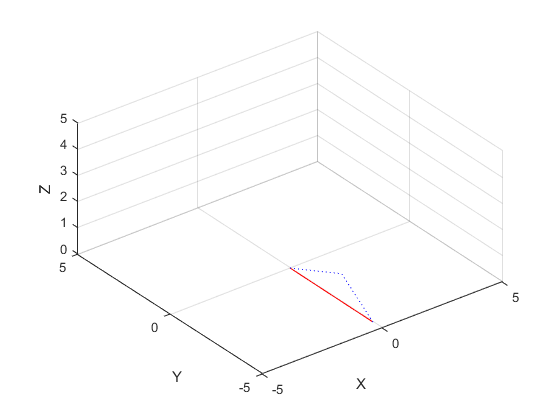


T = [x y z]; % Define Target vector coordinates.

a = norm(T); % Normalise target vector to find dispacement from origin to target.
b = 3; % Length of bicep.
c = 2; % Length of forarm.

% calculate angles 
A = acosd((b^2 + c^2 - a^2) / (2 * b * c));
%B = acosd((a^2 + c^2 - b^2) / (2 * a * c));
C = acosd((a^2 + b^2 - c^2) / (2 * a * b));

theta = atand(T(2)/T(1));
phi = 90-(asind(T(3)/a)+C);

if T(1) < 0
    theta = theta - 180;
end

Bv = [0 0 0];

Bv(1) = b * sind(phi) * cosd(theta);
Bv(2) = b * sind(phi) * sind(theta);
Bv(3) = b * cosd(phi);

figure;
hold on;
plot3([O(1) T(1)], [O(2) T(2)], [O(3) T(3)], 'r')
plot3([O(1) Bv(1)], [O(2) Bv(2)], [O(3) Bv(3)], 'b:')
plot3([T(1) Bv(1)], [T(2) Bv(2)], [T(3) Bv(3)], 'b:')

% Format plot
axis equal;
xlim([-5 5]);
ylim([-5 5]);
zlim([0 5]);
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
view(3); % Set 3D view


%Joint angles
theta       %base angle (FUNKY FIX)

theta = -90

90-phi      %sholder angle (good)

ans = 20.7419

A           %elbow angle

A = 127.1689